# Control and Instrumentation Lab Assignment 4

**SWARNENDU PAUL 19EE3FP18**

**Q9.**

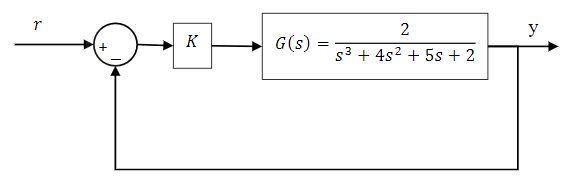

For the given feedback system with proportional controller,


$$Y(s)=\frac{KG(s)}{1+KG(s)}R(s)$$


So, $E(s)=\frac{1}{1+KG(s)}R(s)$

For step input, $R(s)=\frac{1}{s}$

So steady state error for step reference input, 


$$e_{ss}=\frac{1}{1+K\lim_{s \to 0}G(s)}$$
 

So in this case $e_{ss}=\frac{1}{1+K}$ As $G(s)$ have all the poles(-2,-1,-1) in LHP.

so $\frac{1}{1+K}\leq0.15$ or $K\geq \frac{17}{3}$

using rhc we can also find the range of K for the stability of the system. 

Characteristic equation,


$$1+KG(s)=0$$



$$s^3+4s^2+5s+2+2K=0$$


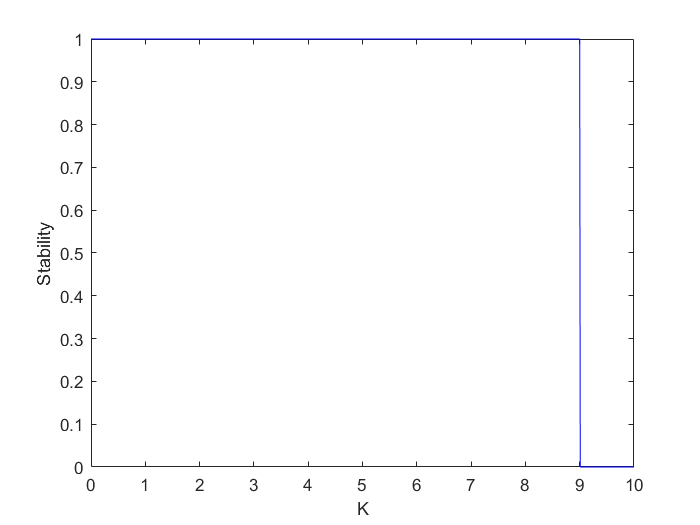

k=0:0.01:10;
y=zeros(size(k));
for i =1:length(k)
    y(i)=rhc([1,4,5,2+2*k(i)],0);
end
figure;
plot(k,y,"b-")
xlabel("K");
ylabel("Stability");

Hence for $\frac{17}{3}\leq K <9$ the system has steady state error less than 15% of the magnitude of step reference input.

Now lets plot the $e_{ss}$ vs $K$ graph.

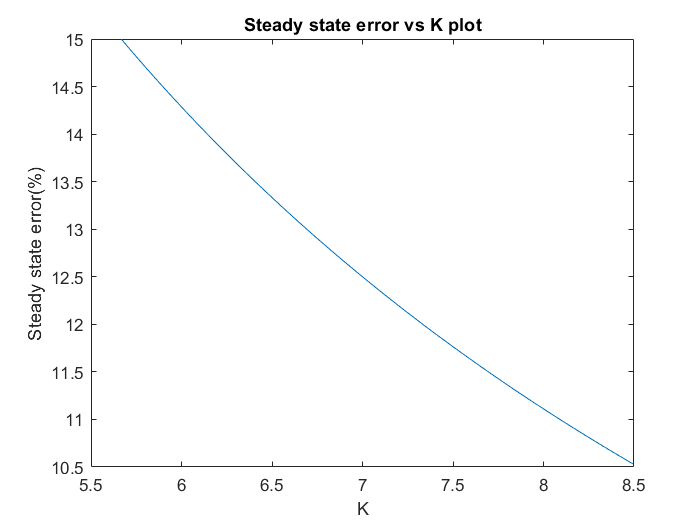

K=17/3:1e-2:8.5;
error=zeros(size(K));
for i=1:length(K)
    [y,t]=step(tf(2*K(i),[1,4,5,2+2*K(i)]),500);
    error(i)=100*abs(1-y(end));
end
figure;
plot(K,error);
xlabel("K");
ylabel("Steady state error(%)");
title("Steady state error vs K plot");

The error gradually decreases till $K<9$. Then the system becomes unstable.

**Q10.**

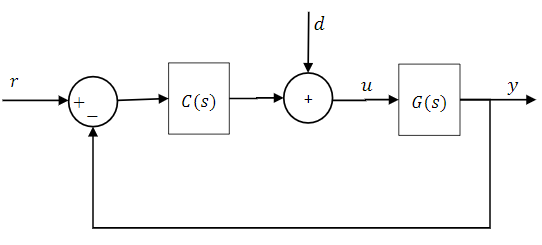

**Case-I:**


$$G(s)=\frac{1}{s-1}$$



$$C(s)=\frac{s-1}{s+1}$$


r-to-y and r-to-u:

Simulink model:

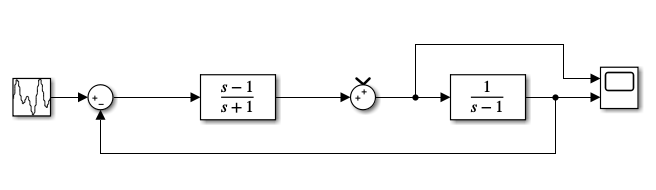

Step responses:

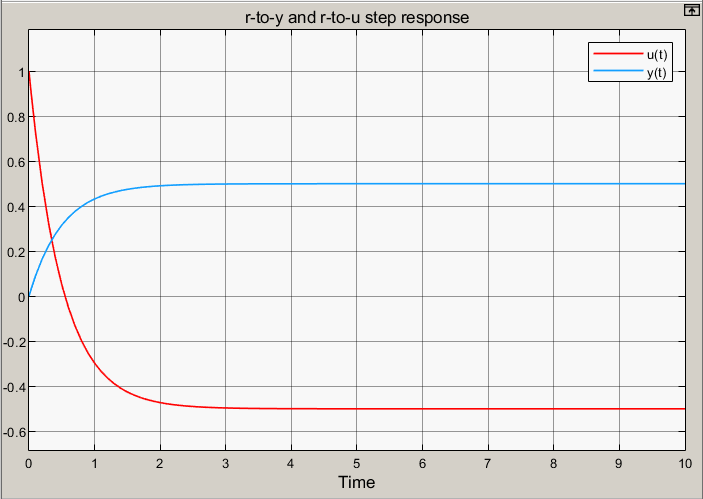

d-to-y and d-to-u:

Simulink model:

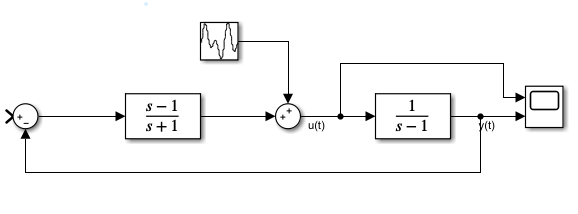

Step responses:

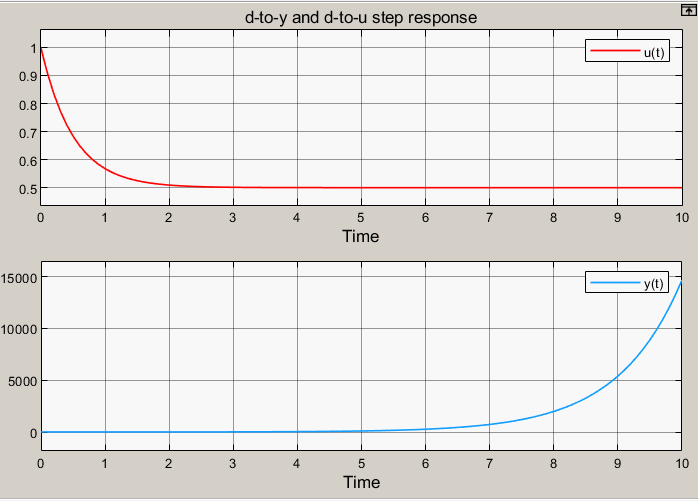

**Case II:**


$$G(s)=\frac{s-1}{s+1}$$



$$C(s)=\frac{1}{s-1}$$


r-to-y and r-to-u:

Simulink model:

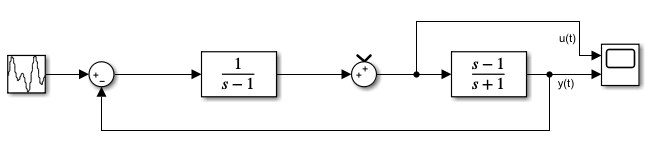

Step response:

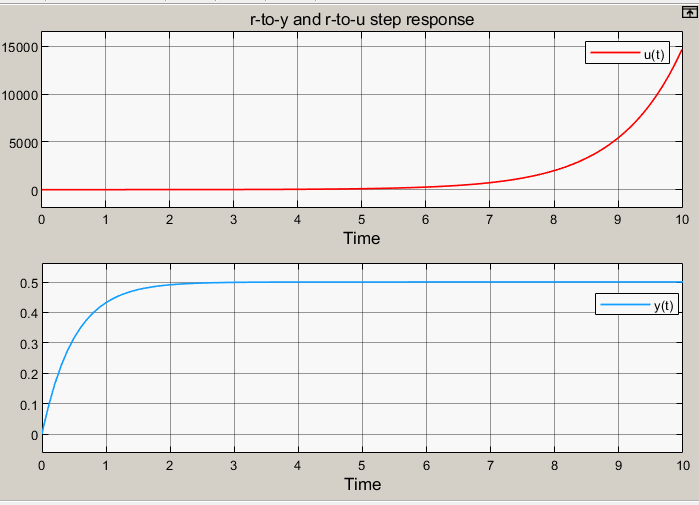

d-to-y and d-to-u:

Simulink model:

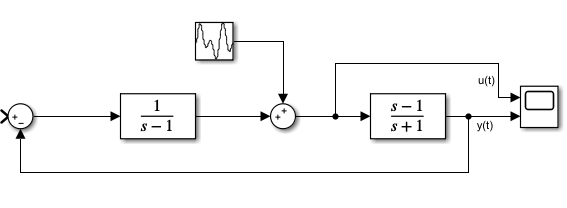

Step response:

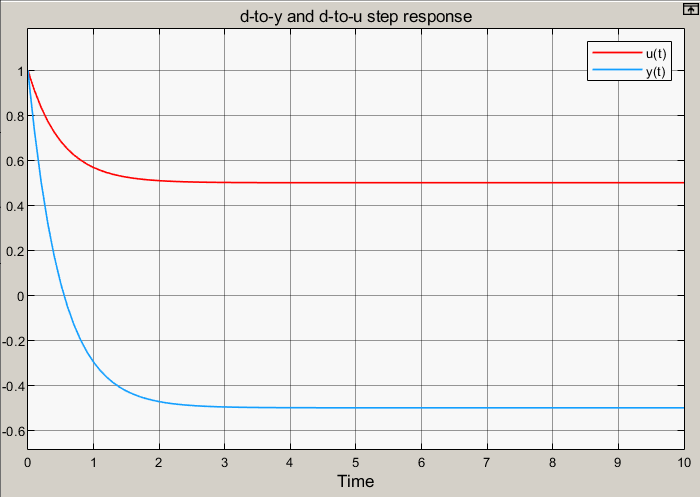

**Case 1: **Considering d as disturbance in system, the 1st system behaves uncontrollably in case of disturbance as u(t) is unstable for d-to-u, So for even a little disturbance in system, output at u will reach saturation, changing the system output y. 

**Case 2: **In 2nd system, disturbance is controlled as both output d-to-u and d-to-y are stable. But the output response at u for reference input is uncontrollable, Which will reach saturation faster and change the output y.